clc
clear
close all

epsilon = [0, 0.02, 0.05, 0.1, 0.15, 0.2, 0.25, 0.3]*100;

out_0_per_1 = load("./sims/rootcut_case1_0_mat.mat").out;
out_2_per_1 = load("./sims/rootcut_case1_0_02_mat.mat").out;
out_5_per_1 = load("./sims/rootcut_case1_0_05_mat.mat").out;
out_10_per_1 = load("./sims/rootcut_case1_0_1_mat.mat").out;
out_15_per_1 = load("./sims/rootcut_case1_0_15_mat.mat").out;
out_20_per_1 = load("./sims/rootcut_case1_0_2_mat.mat").out;
out_25_per_1 = load("./sims/rootcut_case1_0_25_mat.mat").out;
out_30_per_1 = load("./sims/rootcut_case1_0_3_mat.mat").out;

out_0_per_2 = load("./sims2/rootcut_case2_0_mat.mat").out;
out_2_per_2 = load("./sims2/rootcut_case2_0_02_mat.mat").out;
out_5_per_2 = load("./sims2/rootcut_case2_0_05_mat.mat").out;
out_10_per_2 = load("./sims2/rootcut_case2_0_1_mat.mat").out;
out_15_per_2 = load("./sims2/rootcut_case2_0_15_mat.mat").out;
out_20_per_2 = load("./sims2/rootcut_case2_0_2_mat.mat").out;
out_25_per_2 = load("./sims2/rootcut_case2_0_25_mat.mat").out;
out_30_per_2 = load("./sims2/rootcut_case2_0_3_mat.mat").out;


vec_data = [];
vec_data(1, 1) = out_0_per_1.vehicle_velocity(end,3);
vec_data(1, 2) = out_2_per_1.vehicle_velocity(end,3);
vec_data(1, 3) = out_5_per_1.vehicle_velocity(end,3);
vec_data(1, 4) = out_10_per_1.vehicle_velocity(end,3);
vec_data(1, 5) = out_15_per_1.vehicle_velocity(end,3);
vec_data(1, 6) = out_20_per_1.vehicle_velocity(end,3);
vec_data(1, 7) = out_25_per_1.vehicle_velocity(end,3);
vec_data(1, 8) = out_30_per_1.vehicle_velocity(end,3);

vec_data(2, 1) = out_0_per_2.vehicle_velocity(end,3);
vec_data(2, 2) = out_2_per_2.vehicle_velocity(end,3);
vec_data(2, 3) = out_5_per_2.vehicle_velocity(end,3);
vec_data(2, 4) = out_10_per_2.vehicle_velocity(end,3);
vec_data(2, 5) = out_15_per_2.vehicle_velocity(end,3);
vec_data(2, 6) = out_20_per_2.vehicle_velocity(end,3);
vec_data(2, 7) = out_25_per_2.vehicle_velocity(end,3);
vec_data(2, 8) = out_30_per_2.vehicle_velocity(end,3);

erros = abs((vec_data + 29.4549218847750)/(-29.4549218847750))*100

erros =    36.1041   35.6923   34.6363   32.7540   30.5252   27.9746   25.4290   23.2465
   36.1041   35.3712   33.7253   30.3489   25.8330   20.1256   14.3762   10.6106


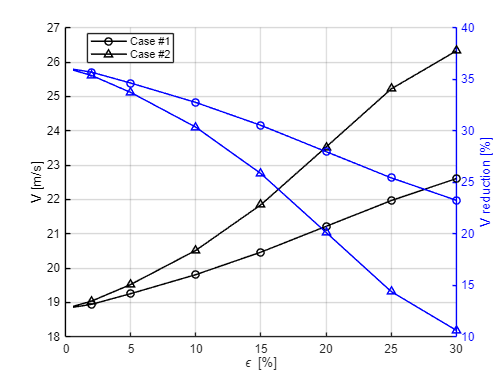


figure()
hold on

yyaxis left
plot(epsilon, -vec_data(1, :), "ko-", 'LineWidth', 1.2)
plot(epsilon, -vec_data(2, :), "k^-", 'LineWidth', 1.2)

% yyaxis right
yyaxis right
plot(epsilon, erros(1, :), "bo-", 'LineWidth', 1.2)
plot(epsilon, erros(2, :), "b^-", 'LineWidth', 1.2)

% Legenda: apenas duas entradas
p1 = plot(nan, nan, 'ko-', 'LineWidth', 1.2, 'DisplayName', 'Case #1');
p2 = plot(nan, nan, 'k^-', 'LineWidth', 1.2, 'DisplayName', 'Case #2');

ylabel('V reduction [%]')
set(gca, 'YColor', 'b')  % eixo da direita a azul

yyaxis left
ylabel('V [m/s]')
set(gca, 'YColor', 'k')  % eixo da esquerda a preto

hold off
grid on
xlabel('\epsilon [%]')
legend([p1 p2], "Location", "best")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'rootcutout_velocity_cases_comp', '-depsc')  % EPS a cores